# Anti-Roll Bar Stiffness Parameter Sweep

This script performs a parameter sweep over different values of stiffness of the anti-roll bar torsion spring for a maneuver with a bump and a double-lane change. Two metrics are computed and results are plotted for each iteration. 

## Design space exploration

### Define the parameter space to explore

In this section we can set the values of stiffness (in $Nm/deg$) to simulate.

use_saved_data = false; % Select check-box to use pre-saved simulation data

if ~use_saved_data
    k = [ 10 75 200];
else
    load( 'sm_car_05_sweep_arb_results.mat' );
end

nSims = numel(k);

### Define the simulations

We create an array of input objects that completely specify what we want to run:

% Call function to set up correct vehicle, maneuver and configuration
modelName = 'sm_car';
open_system(modelName)
if ~use_saved_data
    sm_car_05_setup_bump_dlc(modelName);
    Vehicle = sm_car_vehcfg_checkConfig(Vehicle);
    
    % Initialise empty Simulation Input Object
    in = Simulink.SimulationInput.empty(0,nSims);
    
    % Switch off the Mechanics Explorer
    set_param(modelName,'SimMechanicsOpenEditorOnUpdate','off');
    
    for iSim = 1:nSims
    	% Define the model
    	in(iSim) = Simulink.SimulationInput(modelName);
    	% Define parameter values
    	in(iSim) = in(iSim).setVariable('Vehicle.Chassis.SuspA1.AntiRollBar.k.Value',k(iSim));
    	in(iSim) = in(iSim).setVariable('Vehicle.Chassis.SuspA2.AntiRollBar.k.Value',k(iSim));
    	% Define model settings
    	in(iSim) = in(iSim).setModelParameter('StopTime','25');
    	% Attach post simulation analysis
    	in(iSim) = in(iSim).setPostSimFcn(@(y) sm_car_05_sweep_arb_metrics_attach(y));
    end % for
    disp("Ready for simulation")
end % if

Ready for simulation


### Run simulations

Run the simulations using the Simulink Input Object we just defined. Monitor progress through Simulation Manager.

% Avoid warnings from inactive variants
warning off SimulinkBlock:Foundation:RuntimeAccessInvalidSource
warning off Simulink:Logging:RefMdlOverrideUpdated

if ~use_saved_data
    if(verLessThan('matlab','9.8'))
        simOut = sim(in,'ShowSimulationManager', 'on','ShowProgress','on');
    else
        simOut = sim(in,'UseFastRestart','on','ShowSimulationManager', 'on','ShowProgress','on');
    end
end 

[04-Mar-2023 22:06:22] Running simulations...


[04-Mar-2023 22:08:08] Completed 1 of 3 simulation runs


[04-Mar-2023 22:08:29] Completed 2 of 3 simulation runs


[04-Mar-2023 22:08:50] Completed 3 of 3 simulation runs



% Re-enable warning
warning on SimulinkBlock:Foundation:RuntimeAccessInvalidSource 
warning on Simulink:Logging:RefMdlOverrideUpdated

### Plot the results

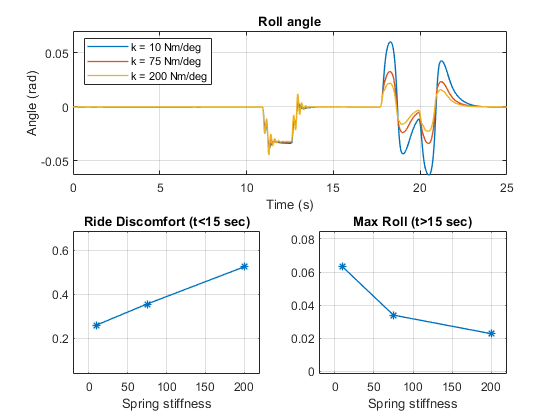

% Clear results figure if it already exists.
if exist('sm_car_sweep', 'var')
    if isgraphics(sm_car_sweep, 'figure')
        clf( sm_car_sweep, 'reset' )
    end
end
sm_car_sweep = figure('Name', 'sm_car_sweep');

% Get results to plot.
if ~use_saved_data
    aRoll = [ simOut.logsout.get("VehBus").Values.Chassis.Body.CG.aRoll ];
    rideDiscomfort = [ simOut.metrics.rideDiscomfort ];
    maxRoll = [ simOut.metrics.maxRoll ];
end % if

for iSim = 1:nSims
    ax(1) = subplot(2, 2, [1 2]);
    plot( aRoll(iSim), 'LineWidth', 1)
    grid on
    hold on
    title('Roll angle')
    ylabel('Angle (rad)')
    xlabel('Time (s)')
end

ax(2) = subplot(2, 2, 3);
plot( k, rideDiscomfort, '*-', 'LineWidth', 1 )
grid on
hold on
title(sprintf('Ride Discomfort (t<15 sec)'))
xlabel('Spring stiffness')

ax(3) = subplot(2, 2, 4);
plot( k, maxRoll, '*-', 'LineWidth', 1 )
grid on
hold on
title(sprintf('Max Roll (t>15 sec)'))
xlabel('Spring stiffness')

% Create legend for roll angle plot.
legend( ax(1), arrayfun( @(x) "k = " + num2str(k(x)) + " Nm/deg", ...
    1:length(k) ), 'Location', 'NorthWest' )

% Resize axes.
set( ax(1), 'YLim', [ax(1).YLim(1) ax(1).YLim(2)+0.01] )
resizeAxes( ax(2) )
resizeAxes( ax(3) )

%resizeAxes( ax(4) )
% Switch the Mechanics Explorer back on
set_param(modelName,'SimMechanicsOpenEditorOnUpdate','on');

function resizeAxes( ax )

ylim_curr = get( ax, 'YLim' );
y_increment = ( ylim_curr(2) - ylim_curr(1) )/2;
xlim_curr = get( ax, 'XLim' );
x_increment = ( xlim_curr(2) - xlim_curr(1) )/10;
set( ax, 'XLim', [ xlim_curr(1)-x_increment xlim_curr(2)+x_increment ] )
set( ax, 'YLim', [ ylim_curr(1)-y_increment ylim_curr(2)+y_increment ] )

end

## Benefits of using input objects:

- Support for sim, parsim, batchsim

- Manipulate model and simulation parameters without actually modifying the model

- Run post-simulation analysis and gather results to a single simulation output object

- In-built progress display + Simulation Manager

- Automated clean up, such as reverting from Fast Restart